# **Admittance Matrix 1:**

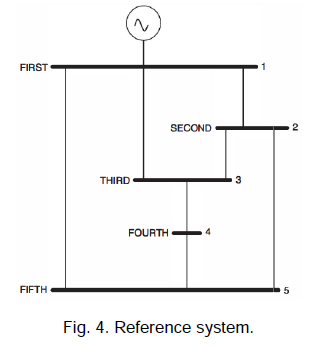

nbb=5; % Number of buses
ntl=7; % Number of Lines
P=[0 40 25 40 50];
Q=[0 20 15 20 20];
S=(-P-1i*Q)/100; % Base MVA is 100 and both p and q are represented as negative powers to represent tlsend=[1 1 1 2 2 3 4]; % Sending ends of lines
tlsend=[1 1 1 2 2 3 4]; % Sending ends of lines
tlrec=[2 5 3 3 5 4 5]; % Receiving ends of lines
tlresis=[0.05 0.03 0.05 0.04 0.04 0.06 0.04]; % Resistances of lines
tlreac=[0.1100 0.0800 0.1100 0.0900 0.0900 0.1300 0.0900]; % Reatances of lines
tlcond=[0 0 0 0 0 0 0]; % Shunt Conductance of lines
tlsuscep=[0.02 0.02 0.02 0.02 0.02 0.03 0.02]; % Shunt susceptance
YR=zeros(nbb,nbb);
YI=zeros(nbb,nbb);
for kk = 1: ntl
ii = tlsend(kk);
jj = tlrec(kk);
denom = tlresis(kk)^2+tlreac(kk)^2;
YR(ii,ii) = YR(ii,ii) + tlresis(kk)/denom + 0.5*tlcond(kk);
YI(ii,ii) = YI(ii,ii) - tlreac(kk)/denom + 0.5*tlsuscep(kk);
YR(ii,jj) = YR(ii,jj) - tlresis(kk)/denom;  %Y12=-yab;
YI(ii,jj) = YI(ii,jj) + tlreac(kk)/denom;
YR(jj,ii) = YR(jj,ii) - tlresis(kk)/denom;
YI(jj,ii) = YI(jj,ii) + tlreac(kk)/denom;
YR(jj,jj) = YR(jj,jj) + tlresis(kk)/denom + 0.5*tlcond(kk);
YI(jj,jj) = YI(jj,jj) - tlreac(kk)/denom + 0.5*tlsuscep(kk);
end
Y=YR+1i*YI

Y =   10.9589 -25.9974i  -3.4247 + 7.5342i  -3.4247 + 7.5342i   0.0000 + 0.0000i  -4.1096 +10.9589i
  -3.4247 + 7.5342i  11.6721 -26.0609i  -4.1237 + 9.2784i   0.0000 + 0.0000i  -4.1237 + 9.2784i
  -3.4247 + 7.5342i  -4.1237 + 9.2784i  10.4752 -23.1191i  -2.9268 + 6.3415i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -2.9268 + 6.3415i   7.0505 -15.5948i  -4.1237 + 9.2784i
  -4.1096 +10.9589i  -4.1237 + 9.2784i   0.0000 + 0.0000i  -4.1237 + 9.2784i  12.3570 -29.4856i


i am adding this line to test something.